## Задание 1

function plotPoleZeroMaps(sys, name)
    % Проверка, что входная система является объектом tf
    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Построение карты нулей и полюсов для разомкнутой системы
    figure('Position', [0 0 800 500]);

    subplot(1, 2, 1); % Разделение фигуры на два графика
    pzmap(sys);
    % grid on;
    title('Нули и полюса разомкнутой системы');
    xlabel('Re');
    ylabel('Im');
    
    % Создание замкнутой системы с обратной связью
    sys_closed = feedback(sys, 1);

    % Построение карты нулей и полюсов для замкнутой системы
    subplot(1, 2, 2);
    pzmap(sys_closed);
    % grid on;
    title('Нули и полюса замкнутой системы');
    xlabel('Re');
    ylabel('Im');

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotStepResponses(sys, name)
    %   График переходных характеристик для разомкнутой и замкнутой систем.

    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Создаем фигуру для отображения
    figure('Position', [100, 100, 1200, 500]); % Широкая фигура для сравнения

    % Переходная характеристика разомкнутой системы
    subplot(1, 2, 1);
    [y_open, t_open] = step(sys);
    plot(t_open, y_open, 'b', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "разомкнутой системы"});

    % Переходная характеристика замкнутой системы
    sys_closed = feedback(sys, 1);
    subplot(1, 2, 2);
    [y_closed, t_closed] = step(sys_closed);
    plot(t_closed, y_closed, 'r', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "замкнутой системы"});

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotNyquist(sys, name)
    figure('Position', [100, 100, 1000, 800]);
    w = 0:0.01:30000;
    nyquist(sys, w);
    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotBode(sys, name)
    % Создание фигуры
    figure('Position', [0 0 800 600]);
    
    % Получение данных для Bode-графика
    [mag, phase, w] = bode(sys);
    mag = squeeze(20*log10(mag)); % Преобразуем в dB
    phase = squeeze(phase);      % Преобразуем в градусы
    
    % Построение графика амплитуды
    subplot(2, 1, 1);
    hold on;

    % Закрашиваем область, где амплитуда больше 0 дБ
    valid_indices = mag > 0;  % Logical indices where mag > 0
    w_filtered = w(valid_indices);  % Filtered w
    mag_filtered = mag(valid_indices);  % Filtered mag
    % Ensure the data is closed for fill (return to baseline)
    w_fill = [w_filtered; flipud(w_filtered)];  % Duplicate and reverse for closure
    mag_fill = [mag_filtered; zeros(size(mag_filtered))];  % Close to baseline

    fill_area = fill(w_fill, mag_fill, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

    bode_line_mag = plot(w, mag, 'b', 'LineWidth', 1.5); % Амплитудный график
    grid on;
    set(gca, 'XScale', 'log'); % Логарифмическая ось частот
    xlabel('Frequency (rad/s)');
    ylabel('Magnitude (dB)');
    title('Bode Magnitude Plot');
    ylim([min(mag) - 10, max(mag) + 10]); % Настройка диапазона амплитуды
    legend([fill_area, bode_line_mag], {'Magnitude > 0 dB', 'Magnitude'}, 'Location', 'best');
    
    % Построение графика фазы
    subplot(2, 1, 2);
    hold on;
    bode_line_phase = plot(w, phase, 'b', 'LineWidth', 1.5); % Фазовый график
    
    % Рисуем линии на фазовом графике
    k_max = 3; % Максимальное значение k
    phase_lines = [];
    for k = 0:k_max
        phi_plus = (2*k+1)*180;   % +pi в градусах
        phi_minus = -(2*k+1)*180; % -pi в градусах
        line_plus = yline(phi_plus, '--r', 'LineWidth', 1);
        line_minus = yline(phi_minus, '--r', 'LineWidth', 1);
        phase_lines = [phase_lines, line_plus, line_minus]; %#ok<AGROW>
    end
    
    % Поиск частот, где амплитуда пересекает 0 дБ
    zero_crossings = find(diff(sign(mag)) ~= 0);
    vertical_lines = [];
    for idx = zero_crossings'
        v_line = xline(w(idx), '--k', 'LineWidth', 1.5);
        vertical_lines = [vertical_lines, v_line]; %#ok<AGROW>
    end
    
    grid on;
    set(gca, 'XScale', 'log'); % Логарифмическая ось частот
    xlabel('Frequency (rad/s)');
    ylabel('Phase (deg)');
    title('Bode Phase Plot');
    ylim([min(phase) - 30, max(phase) + 30]); % Настройка диапазона фазы
    
    % Легенда
    legend([bode_line_phase, phase_lines(1), vertical_lines], ...
        {'Phase', '\phi = \pm(2k+1)\pi', 'Amplitude = 0 dB'}, ...
        'Location', 'best');
    
    % Экспорт графика
    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function doTask1(num, den, name)
    open_sys = tf(num, den);
    close_sys = feedback(open_sys, 1);
    ans = "Разомкнутая система"
    pole(open_sys)
    ans = "Замкнутая система"
    pole(close_sys)
    plotNyquist(open_sys, "task_1_" + name + "_nyquist");
    plotPoleZeroMaps(open_sys, "task_1_" + name + "_zeros_poles");
    plotStepResponses(open_sys, "task_1_" + name + "_step");
    plotBode(open_sys, "task_1_" + name + "_bode");
end

### Объект 1

ans = "Разомкнутая система"

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


ans = "Замкнутая система"

ans =  -92.8151 + 0.0000i
  -1.3498 + 0.0000i
  -0.1663 + 1.1765i
  -0.1663 - 1.1765i
   0.4975 + 0.0000i


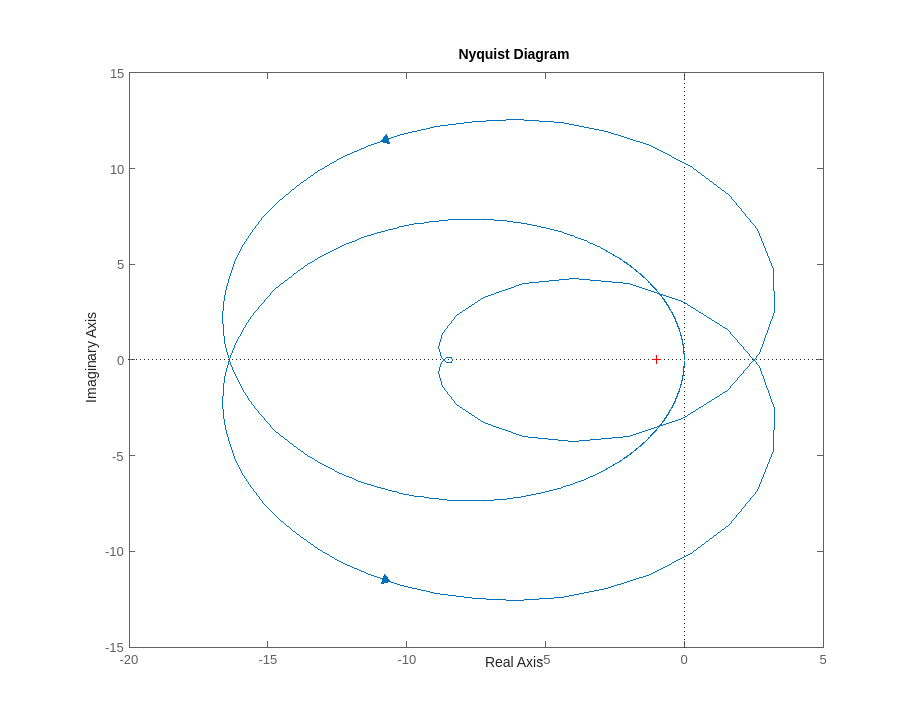

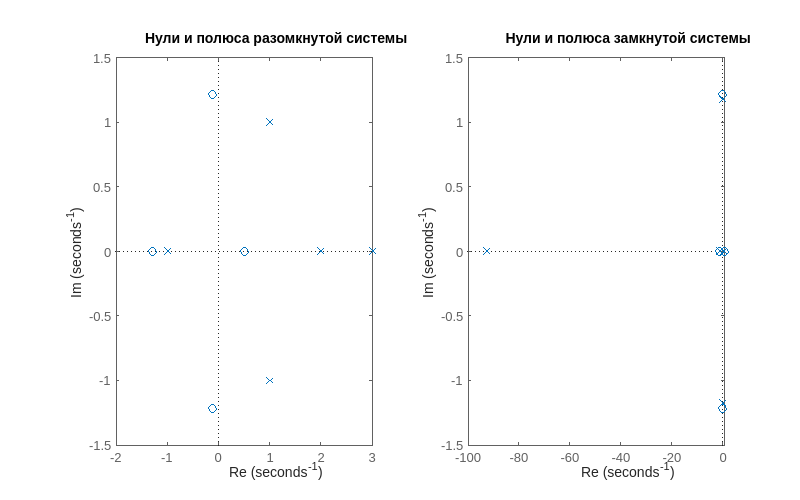

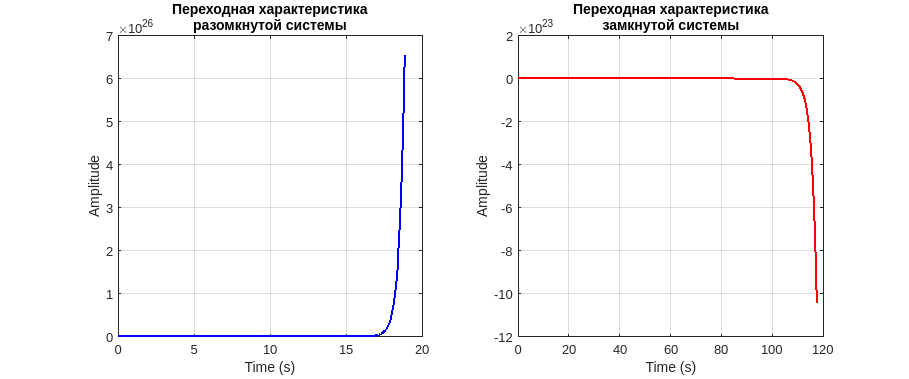

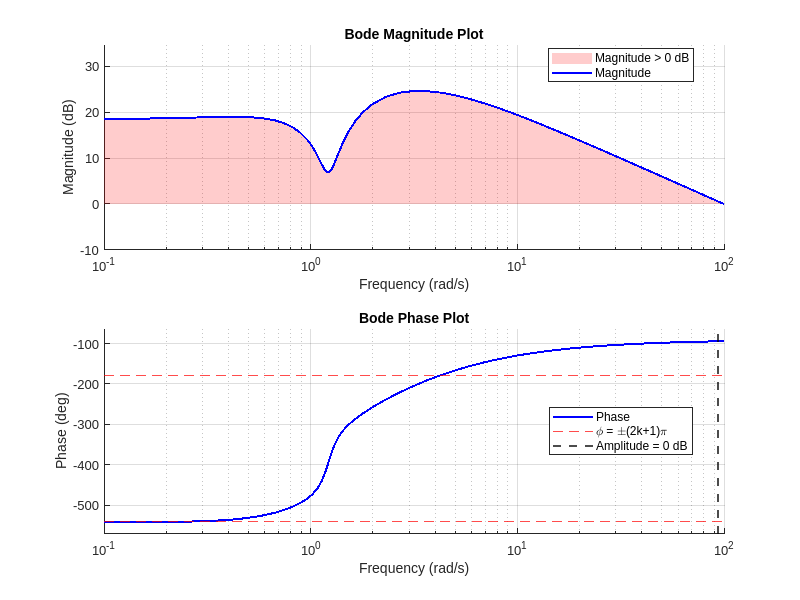

doTask1([100, 100, 100, 100, -100], [1, -6, 11, -4, -10, 12], "obj_1")

### Объект 2

ans = "Разомкнутая система"

ans =   -8.1009 + 0.0000i
  -1.1890 + 4.4248i
  -1.1890 - 4.4248i
  -0.2606 + 0.4630i
  -0.2606 - 0.4630i


ans = "Замкнутая система"

ans =   -8.0765 + 0.0000i
  -1.1348 + 4.4632i
  -1.1348 - 4.4632i
  -0.9676 + 0.0000i
   0.3137 + 0.0000i


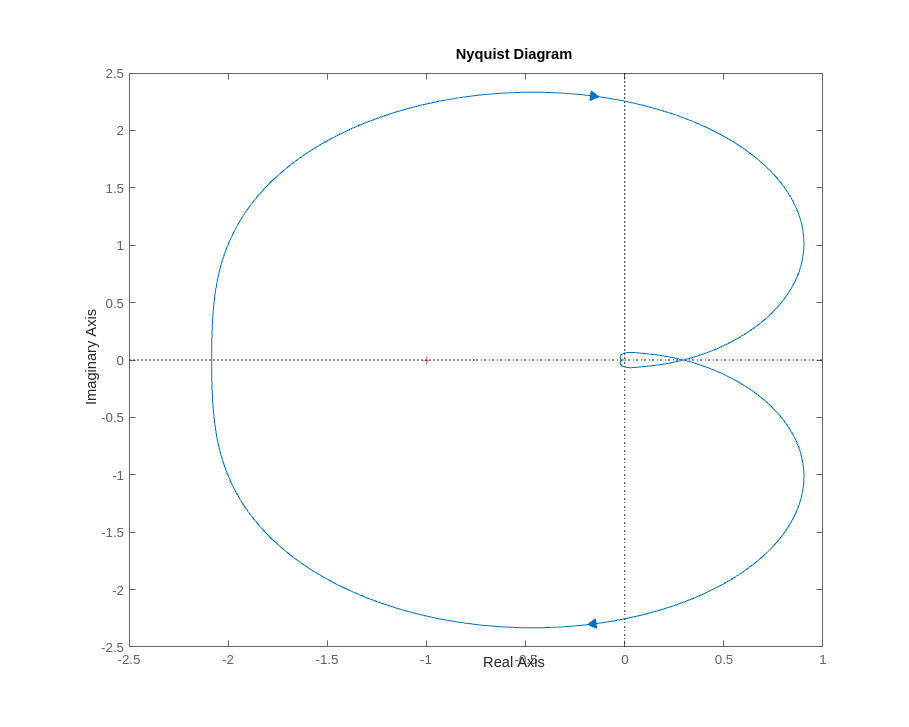

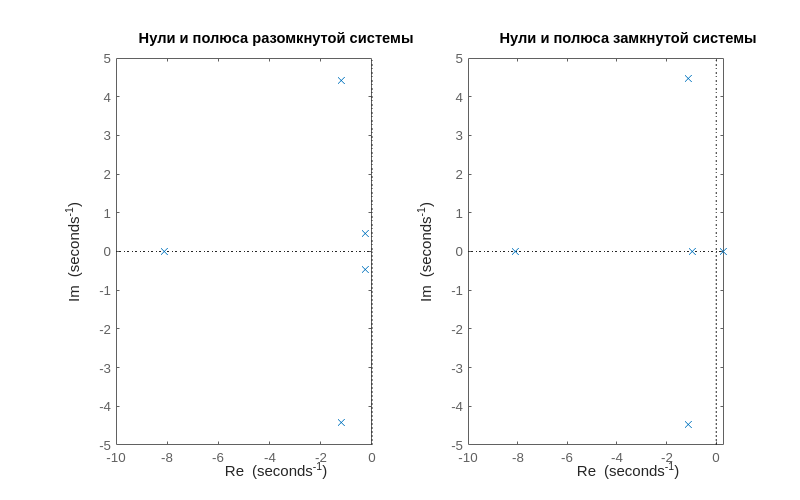

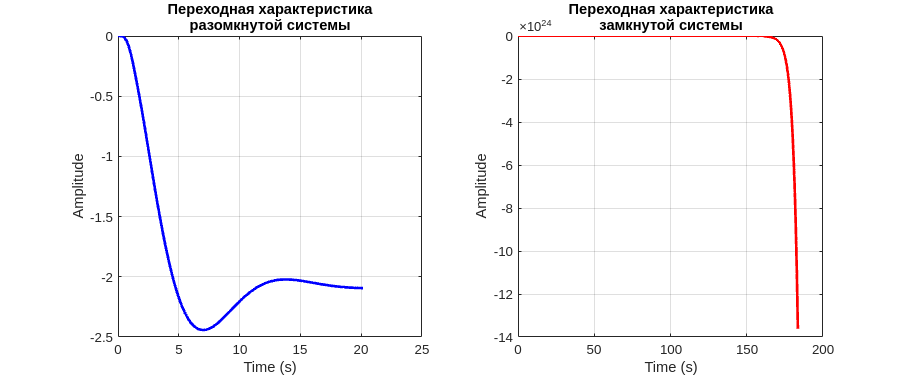

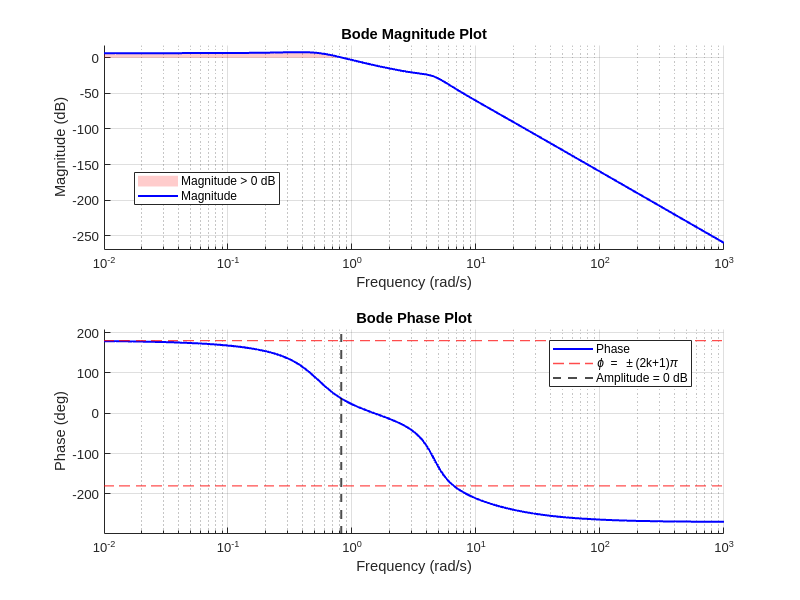

doTask1([-100], [1, 11, 46, 194, 100, 48], "obj_2")

### Объект 3

poly([-10, -1, -10, 0, -10])

ans =            1          31         330        1300        1000           0


ans = "Разомкнутая система"

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


ans = "Замкнутая система"

ans =   -3.8683 +10.7179i
  -3.8683 -10.7179i
  -3.7512 + 0.0000i
  -1.0000 + 0.0000i
  -0.0123 + 0.0000i


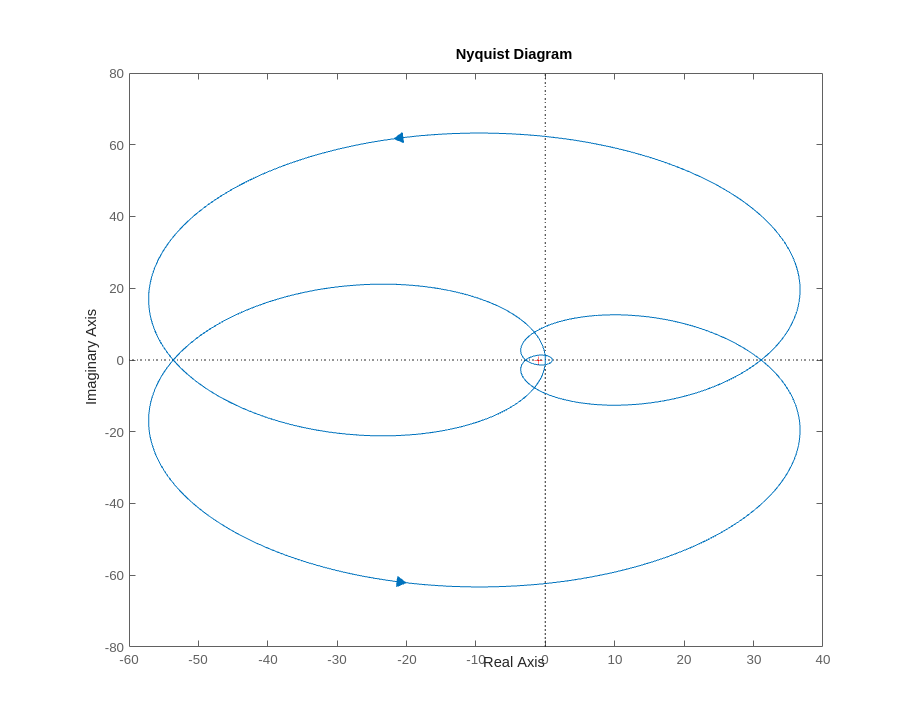

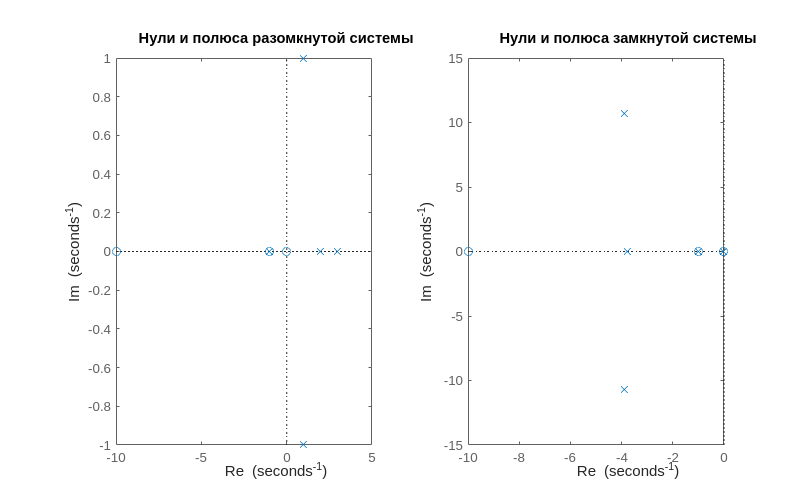

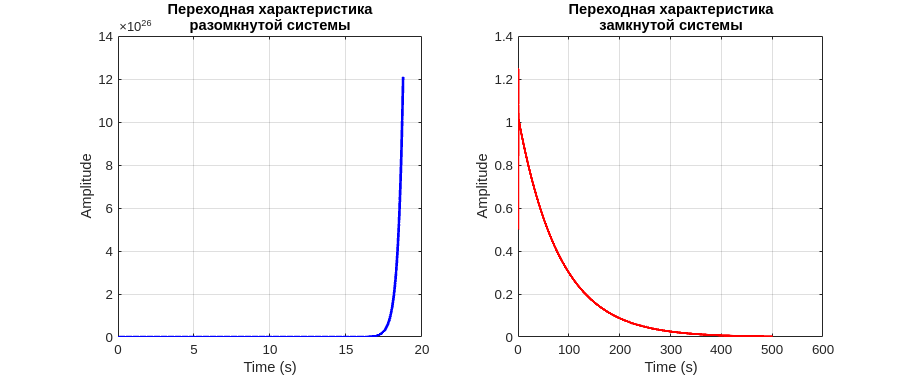

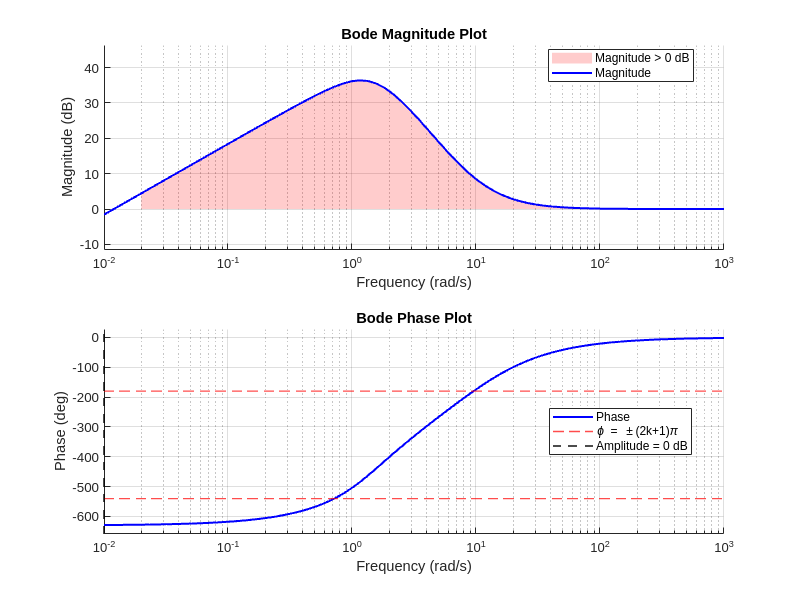

doTask1(poly([-10, -1, -10, 0, -10]), [1, -6, 11, -4, -10, 12], "obj_3")